# 3D Printer Data Exploration

## Load Data

clear;
load 'some_weird_3dprint';

## Test Log Data

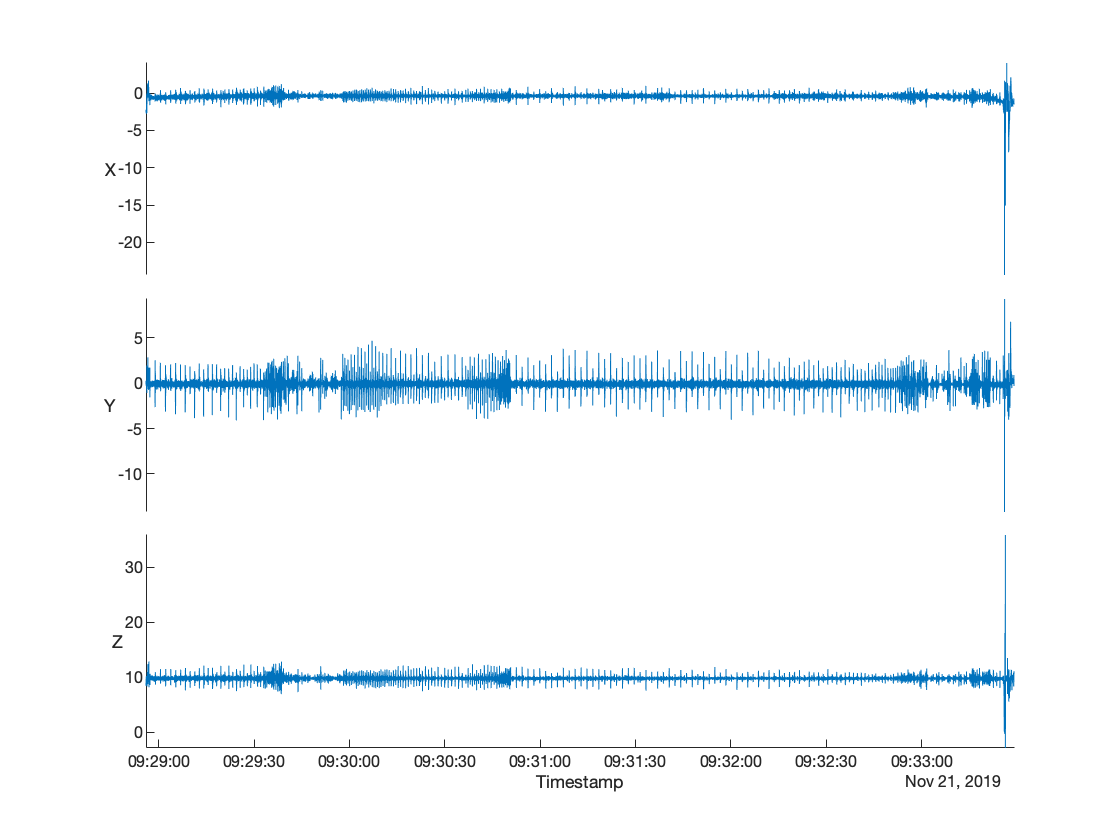

ans =   StackedLineChart with properties:

         SourceTable: [27444×3 timetable]
    DisplayVariables: {'X'  'Y'  'Z'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


stackedplot(Acceleration)

a = timetable2table(Acceleration)

a = 27444×4 table
           Timestamp               X           Y          Z   
    ________________________    _______    _________    ______

    21-Nov-2019 09:28:56.013    -2.5591    -0.085772     8.485
    21-Nov-2019 09:28:56.023    -2.4217       0.1916     8.699
    21-Nov-2019 09:28:56.033    -2.3208      0.28126    8.9716
    21-Nov-2019 09:28:56.043    -2.2581      0.11571    9.3147
    21-Nov-2019 09:28:56.053    -2.2673    -0.059875    9.6248
    21-Nov-2019 09:28:56.063    -2.4652     -0.11017    9.8241
    21-Nov-2019 09:28:56.072    -2.6898     -0.18157    9.9857
    21-Nov-2019 09:28:56.082     -2.792     -0.25178    10.023
    21-Nov-2019 09:28:56.092    -2.7261     -0.29369     9.839
    21-Nov-2019 09:28:56.102     -2.501      -0.2169    9.6832
    21-Nov-2019 09:28:56.112     -2.292    -0.036973    9.6172
    21-Nov-2019 09:28:56.1

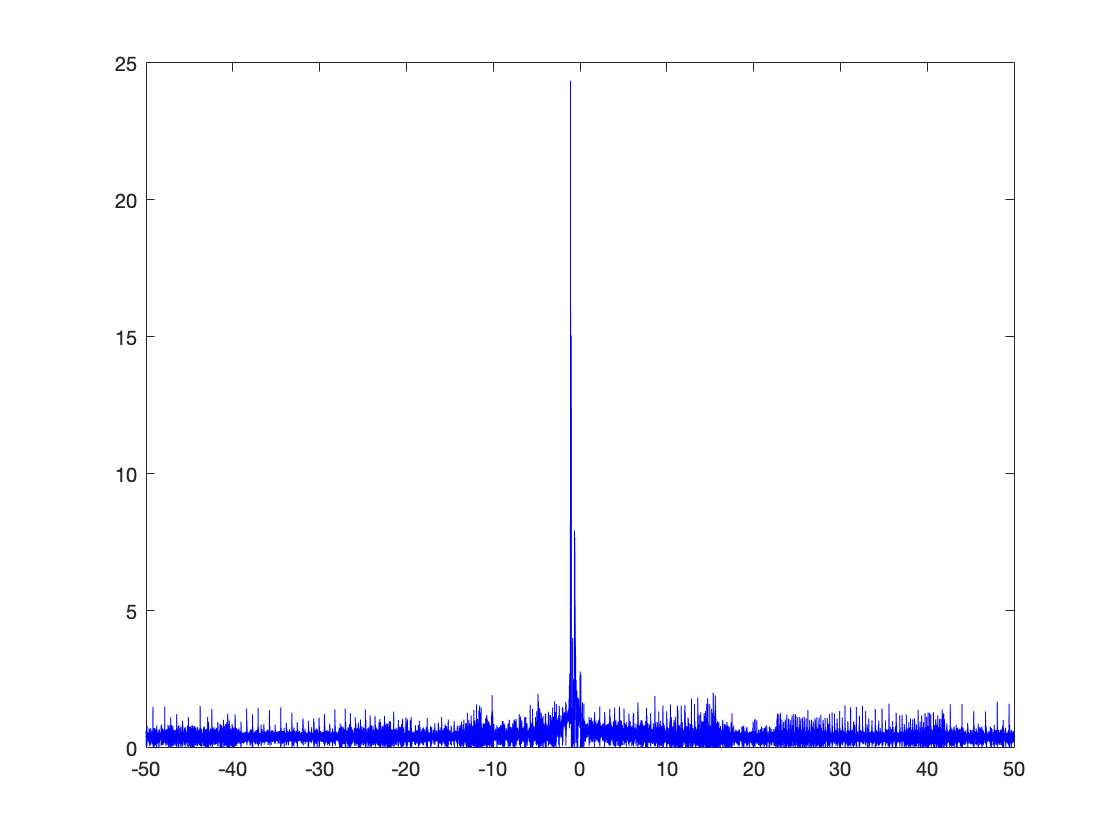

accelData = [a.X a.Y a.Z];
x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(x)),'b');